#### Project Fintech, group 2

*Bucci Teo*

*Cipriani Filippo*

*Corbo Gabriele*

*Fabroni Davide*

*Lucchini Marco*

# Estimating Clients' Needs

## Aim: supervised classification of clients and association with his/her preferred product

We consider a random extraction of a dataset made up of a wealth manager's customers. The data is anonymous, mostly clean and not always normalized/scaled.

We intend to estimate some **investments needs **for these customers using Data Science techniques: we use a bagged tree, optimised with bayesian optimisation, based on one additional feature (time horizon of investment). After we proceed with the association of the client with his/her preferred product. 

We use two dataset called "Needs" and "Products".

In the first dataset we have a table **Needs**, with some relevant features and two responses:

- "AccumulationInvest" which is about **Accumulation investing**, typically using dollar-cost averaging (you invest small amounts of your money at certain intervals over the course of time); the response is boolean: 1 = high propensity | 0 = low propensity;

- "IncomeInvest" which is about **Income investing**, typically through lump sum investing (one shot); the response is boolean: 1 = high propensity | 0 = low propensity.

Among the features, we add a possible time horizon for each client, i.e. the maximum number of years the client is willing to invest for on the same category of products.

In the latter we have a table** Products**  with some products (funds, segregated accounts, unit-linked), their **type** (1 = Accumulation, 0 = Income), and their **risk level** (normalized in the range [0,1]).

Also for this second dataset we add a time horizon for each product, i.e. the greatest time interval describing the product lifetime.

#### *Load data*

close all
clc
% File loading 
load('Needs.mat')
load('Products.mat')

### **Data transformation of Wealth and Income**

We make a Box Cox transformation on *Wealth *and *Income* and we choose to apply the logarithm for a clearer interpretation of results.

Data = Needs; % renaming (we'll likely manipulate this matrix, but we don't touch the original matrix)
% We'll go for the log-transformation
logWealth = log(Data.Wealth);

% We'll go for the log transformation
logIncome = log(Data.Income); 

### Adding Time Horizon

We create a Gaussian random vector in the range [1,10] and we assign randomly each value to the clients. This information is saved in the column `InvestmentTimeHorizon.`

n=6;
min_timehorizon=1;
max_timehorizon=10;
client_time_horizon=floor(min_timehorizon+(max_timehorizon-min_timehorizon)*sum(rand(length(Data.IncomeInvestment),n),2)/n);
Data.InvestmentTimeHorizon=client_time_horizon(:,1);

### Data scaling

Before applying the machine learning techniques we need to rescale our data in order to make them comparable.

There are two possible scaling approaches: z-score (which uses the mean and the standard deviation of the values for any feature) and the min/max (which simply considers the minimum and the maximum).

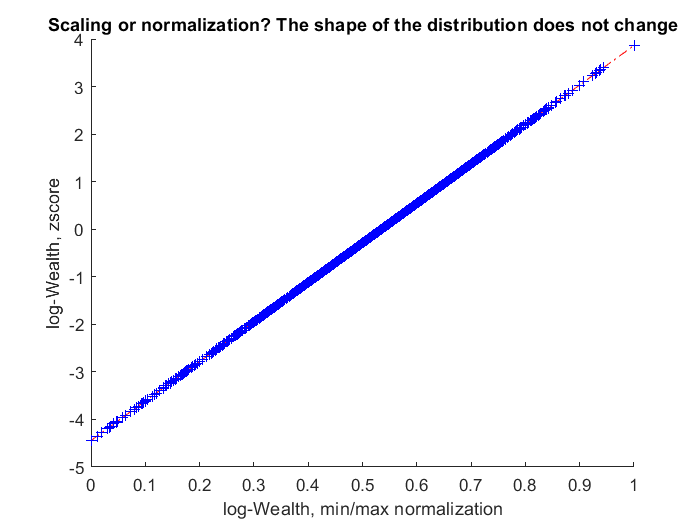

% Comparison between the two scaling approaches
qqplot(rescale(logWealth), zscore(logWealth))
title('Scaling or normalization? The shape of the distribution does not change')
xlabel('log-Wealth, min/max normalization')
ylabel('log-Wealth, zscore')

By observing the result of the qqplot we conclude that the choice of the scaling approach does not affect the distribution shape, so we can indifferently choose the one or the other: we will use the min/max rescaling approach.

% Min/max rescalation 
X =[rescale(Data.Age) Data.Gender rescale(Data.FamilyMembers) rescale(Data.FinancialEducation)...
    rescale(Data.RiskPropensity) rescale(logIncome) rescale(logWealth) rescale(Data.InvestmentTimeHorizon)];

### Dividing our data

We divide data in the training sample and test sample. The proportion we use is 75%-25%;

nObs = size(Data, 1);
idxPermutation = randperm(nObs);
X = X(idxPermutation,:); % random permutation
nObsTrain = round(0.75*nObs);

yInvIncTrain = Data.IncomeInvestment(1:nObsTrain);
yInvIncTest = Data.IncomeInvestment(nObsTrain+1:end);

yInvAccTrain = Data.AccumulationInvestment(1:nObsTrain);
yInvAccTest = Data.AccumulationInvestment(nObsTrain+1:end);

varNames = {'Age', 'Gender', 'Family', 'FinEdu', 'Risk', 'Income', 'Wealth', 'TimeHorizon'};

### Classification models

We follow the financial advisory best practice to refine the process:

- accumulation investment products are mainly intended for relatively young people who have more income than accumulated wealth;

- the "income" investment products are mostly intended for a public that has already accumulated a wealth, and is often older;

- an interesting variable we consider is the ratio income / wealth ratio (eliminating the subjects with too low wealth, otherwise the ratio would explode, and besides that they are not too important in terms of business);

- in order to have a cleaner picture we have eliminated family size and gender, which are perhaps not so decisive (in principle, from a financial advisory perspective they shouldn't be so important).

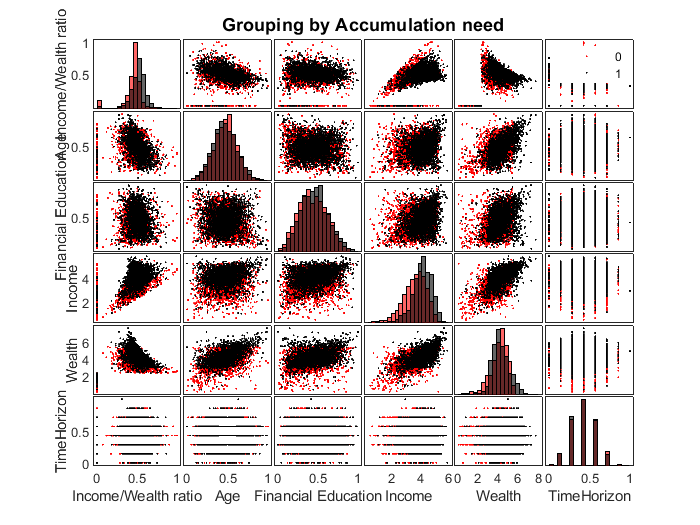

IncomeWealthRatio = zeros(nObs,1);
IncomeWealthRatio(Data.Wealth>10) = logIncome(Data.Wealth>10)./logWealth(Data.Wealth>10);

% Considering the most significant features
Xsmall = [rescale(IncomeWealthRatio) rescale(Data.Age) rescale(Data.FinancialEducation) logIncome logWealth rescale(Data.InvestmentTimeHorizon)];

% Plot of the new scenario Accumulation
figure
xnames = {'Income/Wealth ratio','Age', 'Financial Education', 'Income', 'Wealth', 'TimeHorizon'};
gplotmatrix(Xsmall,[],Data.AccumulationInvestment, ["r", "k"],[],[],[],'grpbars', xnames)
title('Grouping by Accumulation need')

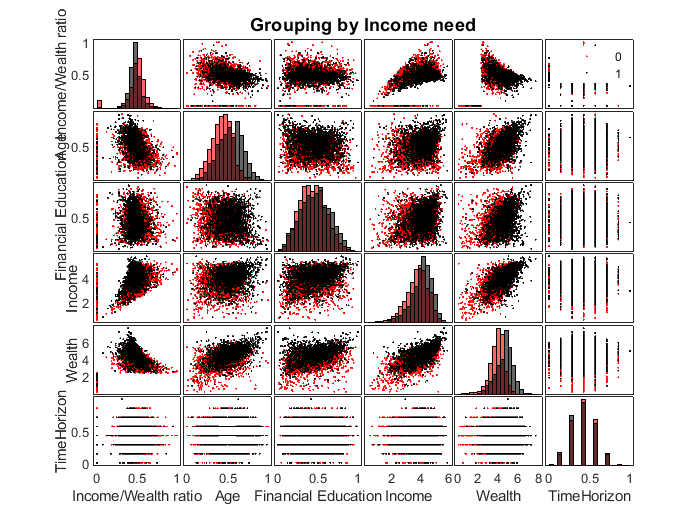

% Plot of the new scenario Income
figure
xnames = {'Income/Wealth ratio','Age', 'Financial Education', 'Income', 'Wealth', 'TimeHorizon'};
gplotmatrix(Xsmall,[],Data.IncomeInvestment, ["r", "k"],[],[],[],'grpbars', xnames)
title('Grouping by Income need')

% Smaller data table 
XsmallTrain = Xsmall(1:nObsTrain,:);
XsmallTest = Xsmall(nObsTrain+1:end,:);
XsmallTrainTable=table(XsmallTrain(:,1), XsmallTrain(:,2), XsmallTrain(:,3), XsmallTrain(:,4), XsmallTrain(:,5), XsmallTrain(:,6), 'VariableNames',xnames);

### Fitting the optimized bagged trees

NOTE: it will take a while.

We fit an optimal ensemble of learners for classification: we automatically optimize ensemble hyperparameters using the function `fitcensemble.` It finds hyperparameters that minimize k-fold cross-validation loss (with K=5) by using automatic hyperparameter optimization. As we specify `'OptimizeHyperparameters'`, the function finds optimal parameters automatically using Bayesian optimization.

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|    1 | Best   |      0.2504 |      6.9907 |      0.2504 |      0.2504 |   AdaBoostM1 |          123 |    0.0018985 |          455 |
|    2 | Best   |     0.18373 |      5.3089 |     0.18373 |     0.18753 |   AdaBoostM1 |           96 |      0.19715 |           16 |
|    3 | Best   |     0.17787 |      1.7033 |     0.17787 |     0.18002 |          Bag |           12 |            - |           18 |
|    4 | Accept |      0.2832 |      1.3409 |     0.17787 |   

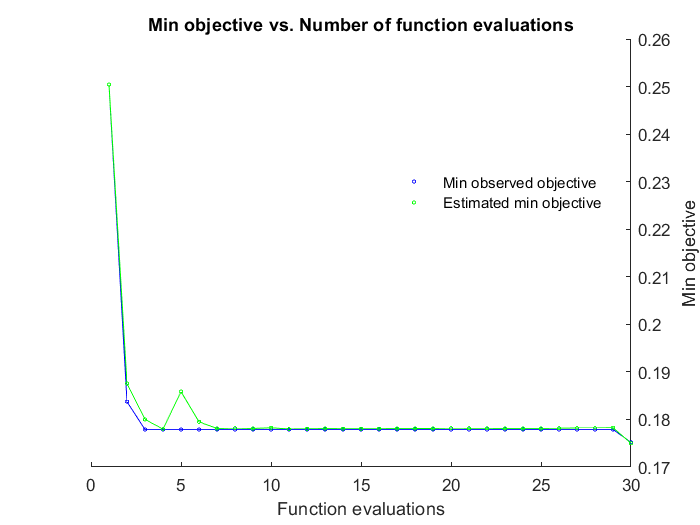


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 243.3714 seconds
Total objective function evaluation time: 201.191

Best observed feasible point:
    Method    NumLearningCycles    LearnRate    MinLeafSize
    ______    _________________    _________    ___________

     Bag             357              NaN           30     

Observed objective function value = 0.1752
Estimated objective function value = 0.17499
Function evaluation time = 24.6845

Best estimated feasible point (according to models):
    Method    NumLearningCycles    LearnRate    MinLeafSize
    ______    _________________    _________    

MdlOptimum_acc =   ClassificationBaggedEnsemble
                       PredictorNames: {'Income/Wealth ratio'  'Age'  'Financial Education'  'Income'  'Wealth'  'TimeHorizon'}
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [0    1]
                       ScoreTransform: 'none'
                      NumObservations: 3750
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                           NumTrained: 357
                               Method: 'Bag'
                         LearnerNames: {'Tree'}
                 ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                              FitInfo: []
                   FitInfoDescription: 'None'
                            FResample: 1
                              Replace: 1
                     Us

% Accumulation fitting
rng('default')
t = templateTree('Reproducible',true); % in order to get reproducible results
MdlOptimum_acc = fitcensemble(XsmallTrainTable,yInvAccTrain,'OptimizeHyperparameters','auto','Learners',t, ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'))

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|    1 | Best   |      0.2424 |      4.4523 |      0.2424 |      0.2424 |   AdaBoostM1 |          123 |    0.0018985 |          455 |
|    2 | Best   |     0.18613 |      4.1463 |     0.18613 |     0.18934 |   AdaBoostM1 |           96 |      0.19715 |           16 |
|    3 | Accept |      0.1896 |     0.98897 |     0.18613 |     0.18777 |          Bag |           12 |            - |           18 |
|    4 | Accept |      0.2424 |     0.85026 |     0.18613 |   

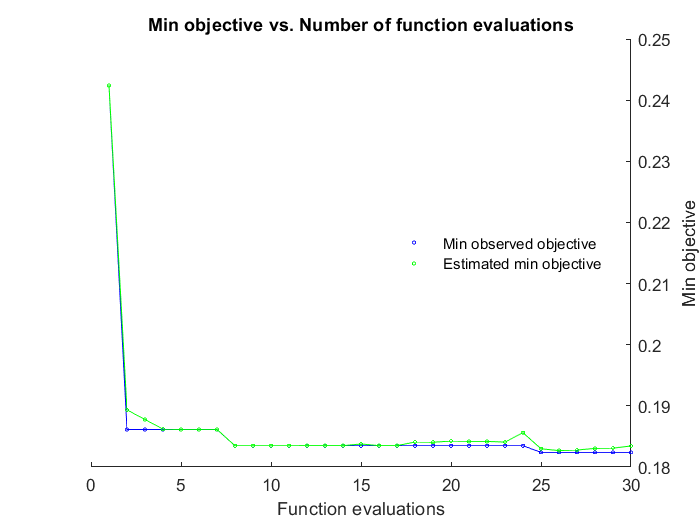


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 250.7783 seconds
Total objective function evaluation time: 217.4087

Best observed feasible point:
    Method    NumLearningCycles    LearnRate    MinLeafSize
    ______    _________________    _________    ___________

     Bag             474              NaN            7     

Observed objective function value = 0.1824
Estimated objective function value = 0.18344
Function evaluation time = 44.2545

Best estimated feasible point (according to models):
    Method    NumLearningCycles    LearnRate    MinLeafSize
    ______    _________________    _________    

MdlOptimum_inc =   ClassificationBaggedEnsemble
                       PredictorNames: {'Income/Wealth ratio'  'Age'  'Financial Education'  'Income'  'Wealth'  'TimeHorizon'}
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [0    1]
                       ScoreTransform: 'none'
                      NumObservations: 3750
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                           NumTrained: 474
                               Method: 'Bag'
                         LearnerNames: {'Tree'}
                 ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                              FitInfo: []
                   FitInfoDescription: 'None'
                            FResample: 1
                              Replace: 1
                     Us

% Income fitting
rng('default')
t = templateTree('Reproducible',true); % in order to get reproducible results
MdlOptimum_inc = fitcensemble(XsmallTrainTable,yInvIncTrain,'OptimizeHyperparameters','auto','Learners',t, ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'))

% We save the models
save("model_accTIME.mat","MdlOptimum_acc");
save("model_incTIME.mat","MdlOptimum_inc");

## Prediction

From each ensemble classifier, `MdlOptimum_acc` and `MdlOptimum_inc` we retrieve:

- predicted labels;

- scores (the confidence that an observation originates from a specific class; the higher the score, the higher the confidence;  `Bag` scores range from `0` to `1: `closer they are to 1 better is the performance of the classification model.

We examine scores,which are probabilities averaged over all the trees in the ensemble, in order to understand how strong is the model conviction.

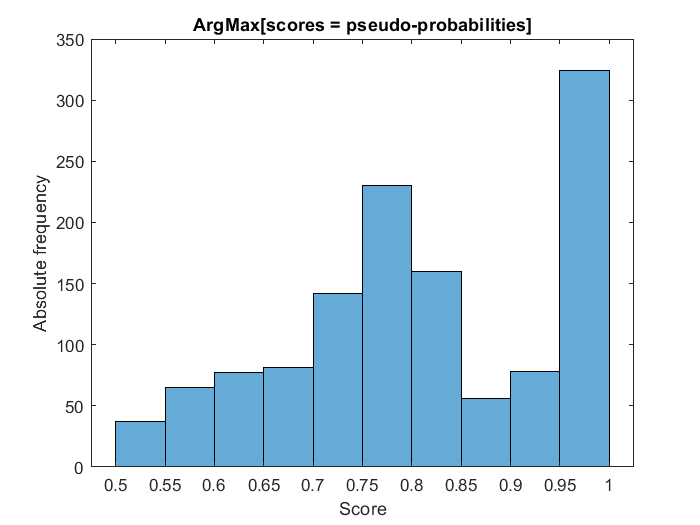

[labels_acc,scores_acc] = predict(MdlOptimum_acc,XsmallTest);

figure
histogram(max(scores_acc')')
title('ArgMax[scores = pseudo-probabilities]')
xlabel('Score')
ylabel('Absolute frequency')

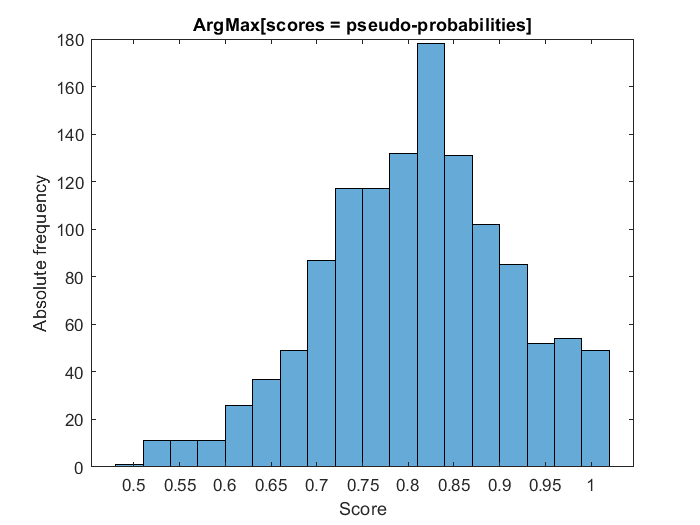

[labels_inc,scores_inc] = predict(MdlOptimum_inc,XsmallTest);

figure
histogram(max(scores_inc')')
title('ArgMax[scores = pseudo-probabilities]')
xlabel('Score')
ylabel('Absolute frequency')

We observe that most scores are close to 1, therefore the model has a strong convinction of its predictions.

### Precision, recall and F1 score for Accumulation need

Let's compute **Precision**, **Recall**, and the **F1 score**, which tell how well the model classifies correctly the Accumulation need of clients to their true value.

% Accumulation products
tp_acc = sum((labels_acc == '1') & (yInvAccTest=='1'));
fp_acc = sum((labels_acc == '1') & (yInvAccTest=='0'));
fn_acc = sum((labels_acc == '0') & (yInvAccTest=='1'));
prec_acc = tp_acc / (tp_acc + fp_acc)

prec_acc = 0.9005

rec_acc = tp_acc / (tp_acc + fn_acc)

rec_acc = 0.7638

F1_acc = 2 * prec_acc * rec_acc / (prec_acc + rec_acc)

F1_acc = 0.8266

### Precision, recall and F1 score for Accumulation need

Let's compute **Precision**, **Recall**, and the **F1 score**, which tell how well the model classifies correctly the Income need of clients to their true value.

% Income products
tp_inc = sum((labels_inc == '1') & (yInvIncTest=='1'));
fp_inc = sum((labels_inc == '1') & (yInvIncTest=='0'));
fn_inc = sum((labels_inc == '0') & (yInvIncTest=='1'));
prec_inc = tp_inc / (tp_inc + fp_inc)

prec_inc = 0.9045

rec_inc = tp_inc / (tp_inc + fn_inc)

rec_inc = 0.6196

F1_inc = 2 * prec_inc * rec_inc / (prec_inc + rec_inc)

F1_inc = 0.7354

In both cases the results indicate that the model classifies Accumulation and Income need, since precision, recall and F1 score are quite close to 1.

### ROC curve

[X_acc,Y_acc,T_acc,AUC_acc,OPTROCPT_acc] = perfcurve(yInvAccTest,scores_acc(:,2),1);
%area under curve
AUC_acc

AUC_acc = 0.8841

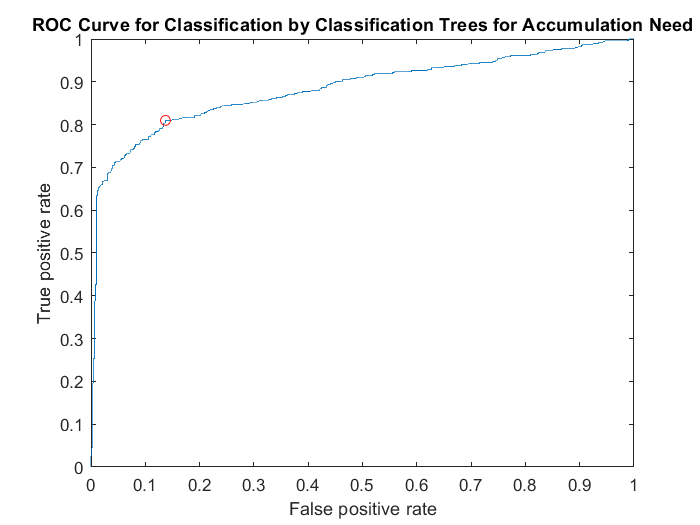

plot(X_acc,Y_acc)
hold on
plot(OPTROCPT_acc(1),OPTROCPT_acc(2),'ro')
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC Curve for Classification by Classification Trees for Accumulation Need')
hold off

%optimal operating point accumulation
OPTROCPT_acc

OPTROCPT_acc =     0.1371    0.8098


%threshold of the optimal operating point
T_acc((X_acc==OPTROCPT_acc(1))&(Y_acc==OPTROCPT_acc(2)))

ans = 0.3840

%income
[X_inc,Y_inc,T_inc,AUC_inc,OPTROCPT_inc] = perfcurve(yInvIncTest,scores_inc(:,2),1);
%area under curve
AUC_inc

AUC_inc = 0.8126

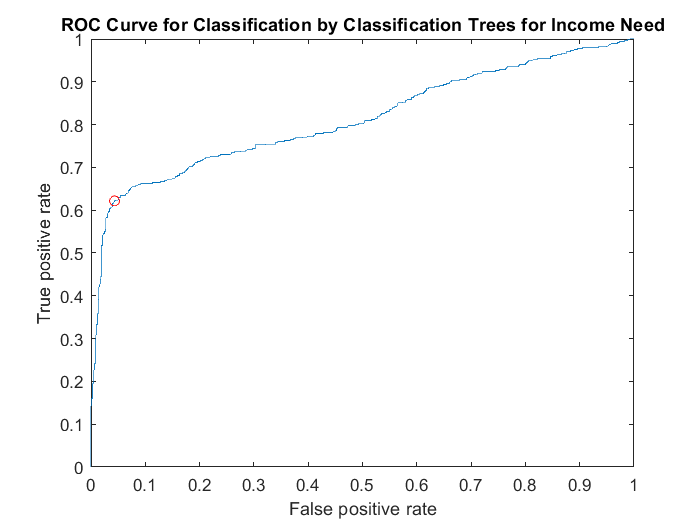

plot(X_inc,Y_inc)
hold on
plot(OPTROCPT_inc(1),OPTROCPT_inc(2),'ro')
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC Curve for Classification by Classification Trees for Income Need')
hold off

%optimal operating point accumulation
OPTROCPT_inc

OPTROCPT_inc =     0.0434    0.6217


%threshold of the optimal operating point
T_inc((X_inc==OPTROCPT_inc(1))&(Y_inc==OPTROCPT_inc(2)))

ans = 0.4815

 The ROC curves show the goodness-of-fit of the model considered. It plots the trade-off between sensitivity (or TPR) and specificity (1 – FPR). 

This curves confirm that our models provide an accurate classification. Moreover the value of the AUC is very close to 1 in both cases.

We observe that the classification of accumulation needs is a bit more accurate than the income ones.

### **Confusion matrices**

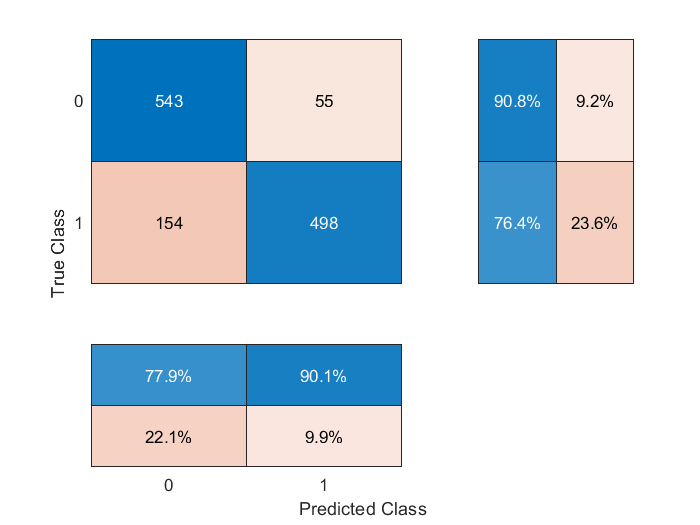

%  Specify 'RowSummary' as 'row-normalized' to display the true positive rates and false positive rates in the row summary. 
%  Also, specify 'ColumnSummary' as 'column-normalized' to display the positive predictive values and false discovery rates in the column summary.
confusionchart(yInvAccTest,labels_acc,'RowSummary','row-normalized','ColumnSummary','column-normalized');

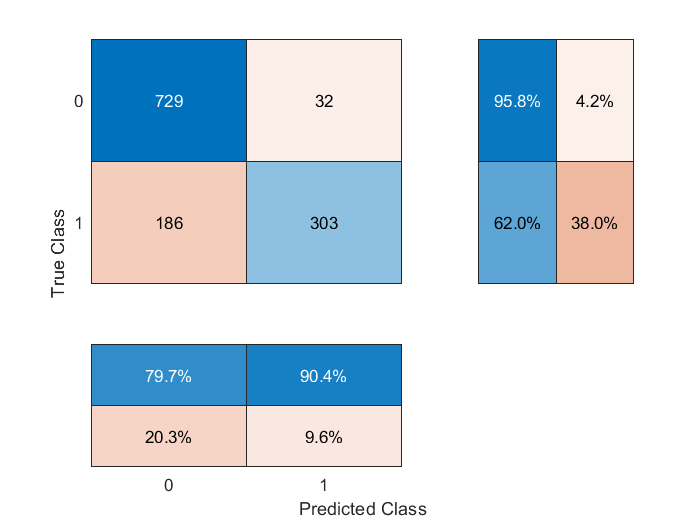

%  Specify 'RowSummary' as 'row-normalized' to display the true positive rates and false positive rates in the row summary. 
%  Also, specify 'ColumnSummary' as 'column-normalized' to display the positive predictive values and false discovery rates in the column summary.
confusionchart(yInvIncTest,labels_inc,'RowSummary','row-normalized','ColumnSummary','column-normalized');

In both cases the model could be improved by reducing the number of false positives: is predicted 0 (no need of accumulation or income product) instead of a true 1 (a need in one of the two).

## Recommending products

Now we generate the personalized recommendation for both the Accumulation products (that is, Products.Type==1) and for the Income Products (that is, Products.Type==0).

We adopt the following rules, for each client:

- **matching product type and client need (predicted using the ensemble model)**;

- **matching product risk and client risk**;

- **suggesting a list of products**, ranked based on a decreasing risk.

For simplicity and to continue the example, we do that for the clients in the test set (but the rules work for an arbitrary set of clients).

Retrieving IDs and risk propensities for the client in the test set, and products (using the variable idxPermutation).

% Retrieving clients IDs
ClientID = Data.ID(idxPermutation);
ClientIDTest = ClientID(nObsTrain+1:end,:);
TargetClientID_acc = ClientIDTest(labels_acc=='1');
TargetClientID_inc = ClientIDTest(labels_inc=='1');

% Retrieving clients' risk propensities
ClientRiskPropensity = Data.RiskPropensity(idxPermutation);
ClientRiskPropensityTest = ClientRiskPropensity(nObsTrain+1:end,:);
TargetClientRiskPropensity_acc = ClientRiskPropensityTest(labels_acc=='1');
TargetClientRiskPropensity_inc = ClientRiskPropensityTest(labels_inc=='1');

% Retrieving clients' time horizon
ClientTimeHorizon= Data.InvestmentTimeHorizon(idxPermutation);
ClientTimeHorizonTest = ClientTimeHorizon(nObsTrain+1:end,:);
TargetClientTimeHorizon_acc = ClientTimeHorizonTest(labels_acc=='1');
TargetClientTimeHorizon_inc = ClientTimeHorizonTest(labels_inc=='1');

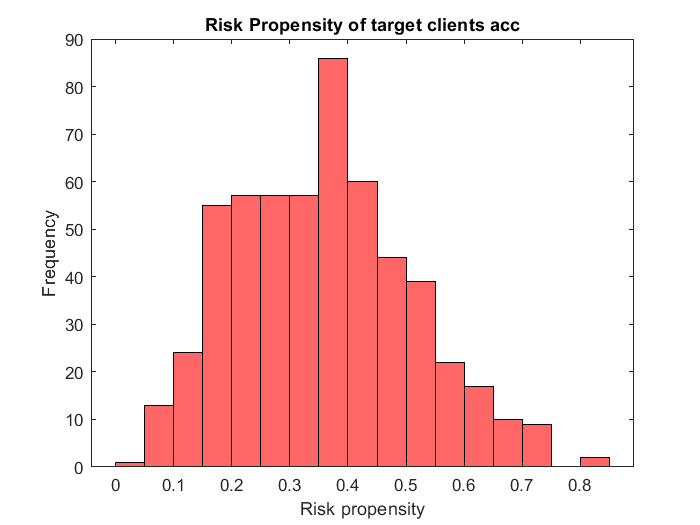

% Let's have a look to risk propensities and time horizon
figure
histogram(TargetClientRiskPropensity_acc, 'FaceColor', 'r')
title('Risk Propensity of target clients acc')
xlabel('Risk propensity')
ylabel('Frequency')

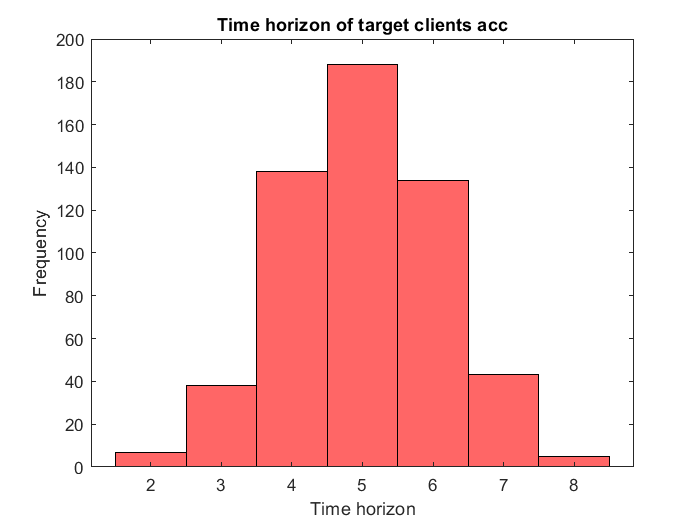


figure
histogram(TargetClientTimeHorizon_acc, 'FaceColor', 'r')
title('Time horizon of target clients acc')
xlabel('Time horizon')
ylabel('Frequency')

### Add products Time Horizon

We assign to each product category the time horizon of investment.

In brief, we have assigned, for Income Products:

- Income Conservative Unit-Linked (Life Insurance) : 5 years;

- Fixed Income Mutual Fund: 8 years;

- Balanced High Dividend Mutual Fund: 7 years;

- Fixed Income Segregated Account: 8 years;

- Term deposits: 2 years.

We have assigned, for Accumulation Products:

- Balanced Mutual Fund: 5 years;

- Balanced Mutual Fund: 5 years;

- Defensive Flexible Allocation Unit-Linked (Life Insurance): 4 years;

- Aggressive Flexible Allocation Unit-Linked (Life Insurance): 7 years;

- Balanced Flexible Allocation Unit-Linkled (Life Insurance): 5 years;

- Cautious Allocation Segregated Account: 6 years;

- Total Return Aggressive Allocation Segregated Account: 9 years.

AccumulationProducts.TimeHorizon=[5 5 4 7 5 6 9]';
IncomeProducts.TimeHorizon=[5 8 7 8 2]';

Products.TimeHorizon = [5 5 8 7 5 4 7 5 6 8 9 2]';
%save("ProductsNEW.mat","Products")
AccumulationProducts = Products(Products.Type == 1,:)

AccumulationProducts = 7×4 table
    ID    Type    Risk    TimeHorizon
    __    ____    ____    ___________

     1     1      0.55         5     
     5     1      0.41         5     
     6     1      0.36         4     
     7     1      0.75         7     
     8     1      0.48         5     
     9     1      0.27         6     
    11     1      0.88         9     


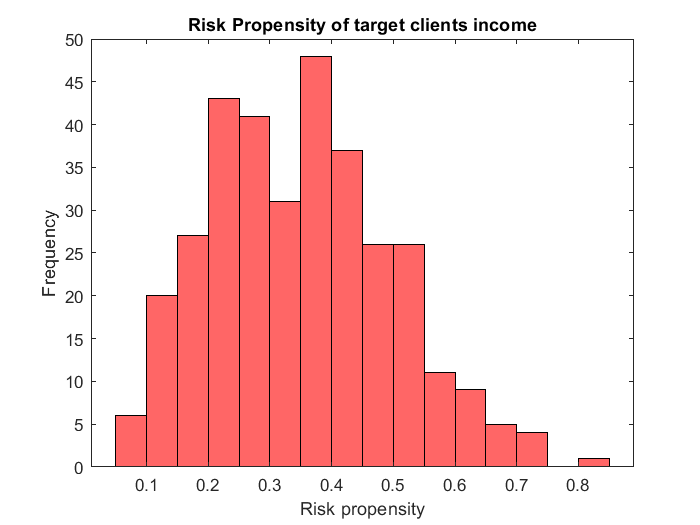

figure
histogram(TargetClientRiskPropensity_inc, 'FaceColor', 'r')
title('Risk Propensity of target clients income')
xlabel('Risk propensity')
ylabel('Frequency')

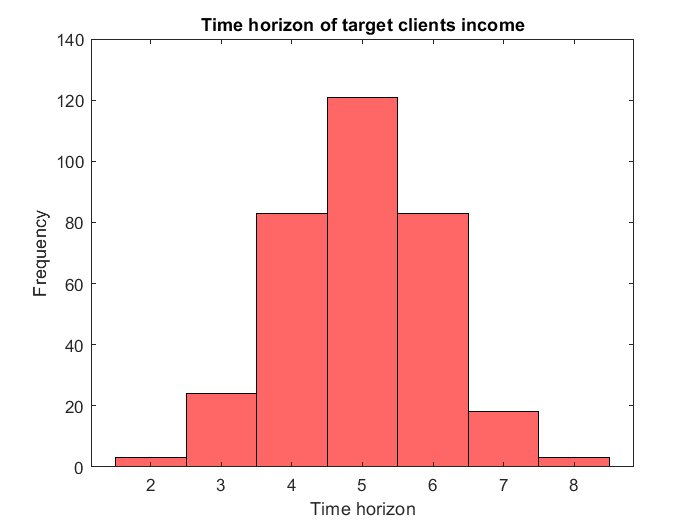

figure
histogram(TargetClientTimeHorizon_inc, 'FaceColor', 'r')
title('Time horizon of target clients income')
xlabel('Time horizon')
ylabel('Frequency')

IncomeProducts = Products(Products.Type == 0,:)

IncomeProducts = 5×4 table
    ID    Type    Risk    TimeHorizon
    __    ____    ____    ___________

     2     0       0.3         5     
     3     0      0.12         8     
     4     0      0.44         7     
    10     0      0.13         8     
    12     0      0.05         2     


### Creating the personalized recommandations:

- The suitable products are those with a risk level below the client risk tolerance;

- Among those products, we have done two classification wrt risk level (more risky) and wrt time horizon (difference between time horizon of client and of the products)

- We add to the products also term deposits, which have a very low risk, in order to find a suitable product also for clients with a lower risk propensity. so, we consider clients with still no associated products: a low risk income product deposito a termine

Accumulation clients case:

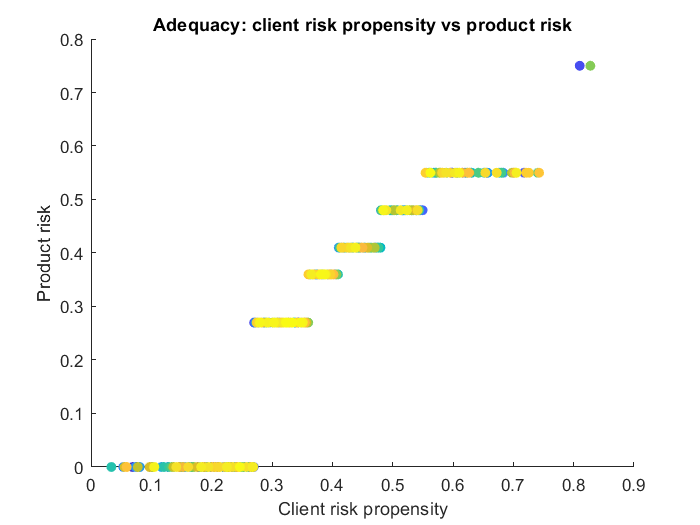

%accumulation 
%inizialization
NBA_IDProduct_acc = zeros(length(TargetClientRiskPropensity_acc),3);
NBA_IDProduct_acc_TH = zeros(length(TargetClientRiskPropensity_acc),3);
RecommendedRiskLevel_acc = zeros(size(TargetClientRiskPropensity_acc, 1),3);
RecommendedTimeHorizon_acc= zeros(size(TargetClientRiskPropensity_acc, 1),3);
minRisk_acc = min(AccumulationProducts.Risk); %minimun risk for accumulation products

z=1;
%Association products-clients with risk propensity
for i= 1:length(TargetClientRiskPropensity_acc)
   v_1=[];
   M_1=[];
   M_1TH=[];
   v_TH=[];
    if TargetClientRiskPropensity_acc(i)>minRisk_acc %check client risk propensity>minimun risk
         
         for j=1:length(AccumulationProducts.ID)
             if AccumulationProducts.Risk(j)<TargetClientRiskPropensity_acc(i)
                 v_1=[v_1 AccumulationProducts.ID(j)];
                 M_1=[M_1 AccumulationProducts.Risk(j)];
                 M_1TH=[M_1TH AccumulationProducts.TimeHorizon(j)];
             end
         end
         %Association of max 3 products wrt Time horizon
         diff_TH=abs(TargetClientTimeHorizon_acc(i)-M_1TH);
         [~,ord]=sort(diff_TH,'ascend');
         if length(diff_TH)>3
               v_TH(1:3)=v_1(ord(1:3));              
               M_TH=M_1TH(ord(1:3));
                
         else
             v_TH=v_1(ord);
             M_TH=M_1TH(ord);
         end
         %Association of max 3 products wrt risk propensities
         if length(v_1)>3
               [M, Ind]= sort(M_1,"descend"); %choose 3 riskier products 
               v(1:3)=v_1(Ind(3:-1:1));              
               M=M(3:-1:1);
                
         else 
                 [M, Ind]= sort(M_1,"ascend"); 
                 v=v_1(Ind);
         end
       NBA_IDProduct_acc(i,1:length(v))=v;
       NBA_IDProduct_acc_TH(i,1:length(v_TH))=v_TH;
       RecommendedRiskLevel_acc(i, 1:length(M))=M;
       RecommendedTimeHorizon_acc(i,1:length(M_TH))=M_TH;
    else
       %clients that cannot be associated (risk too low)
       NONASSOCIATI_acc(z)=TargetClientID_acc(i);
       risk_nonass_acc(z)=TargetClientRiskPropensity_acc(i);
       z=z+1;
    end
end
%NBA_acc collects client_ID and the associated products
NBA_acc=[TargetClientID_acc categorical(NBA_IDProduct_acc)];
NBA_acc_TH=[TargetClientID_acc categorical(NBA_IDProduct_acc_TH)];

%risk_nonassociated_acc collects client_ID and client risk propensity
risk_nonassociated_acc=[double(NONASSOCIATI_acc') risk_nonass_acc' ];
%association of an alternative product DEPOS low risk income
p=1;
q=1;
proposta_alternativa=[];
non_associabili=[];
for k=1:size(risk_nonassociated_acc,1)
    if risk_nonassociated_acc(k,2)>IncomeProducts.Risk(end)
        proposta_alternativa(p,1)=risk_nonassociated_acc(k,1);
        proposta_alternativa(p,2)=risk_nonassociated_acc(k,2);
        p=p+1;
    else 
        %clients that have risk lower than depos risk
        non_associabili(q,1)=risk_nonassociated_acc(k,1);
        non_associabili(q,2)=risk_nonassociated_acc(k,2);
        q=q+1;
    end
end
% INCOME 
%income products
figure
c = linspace(0,1,length(TargetClientRiskPropensity_acc));
scatter(TargetClientRiskPropensity_acc, max(RecommendedRiskLevel_acc,[],2), [], c, 'filled')
title('Adequacy: client risk propensity vs product risk')
xlabel('Client risk propensity')
ylabel('Product risk')

Income clients case:

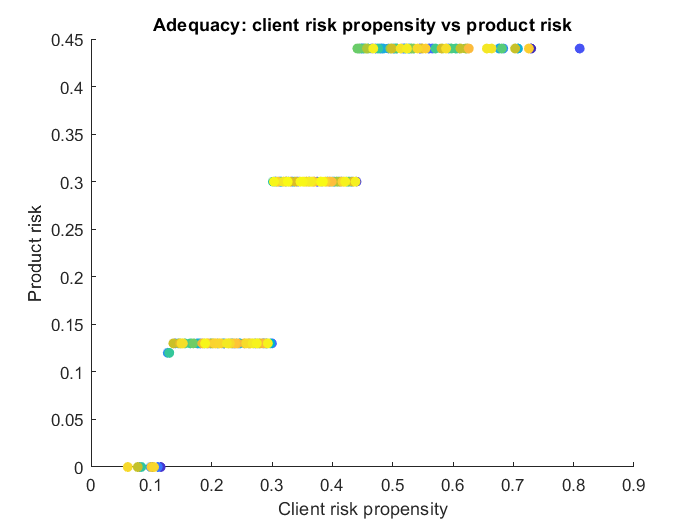

% INCOME 
%income products
%inizialization
NBA_IDProduct_inc = zeros(length(TargetClientRiskPropensity_inc),3);
NBA_IDProduct_inc_TH = zeros(length(TargetClientRiskPropensity_inc),3);
RecommendedRiskLevel_inc = zeros(size(TargetClientRiskPropensity_inc, 1),3);
RecommendedTimeHorizon_inc= zeros(size(TargetClientRiskPropensity_inc, 1),3);
minRisk = min(IncomeProducts.Risk(1:4)); 
z=1;
NONASSOCIATI_inc=[];
%Association products-clients with risk propensity
for i= 1:length(TargetClientRiskPropensity_inc)
   v_1=[];
   M_1=[];
   M_1TH=[];
   v_1TH=[];
    if TargetClientRiskPropensity_inc(i)>minRisk %check client risk propensity>minimun risk
         for j=1:length(IncomeProducts.ID)-1
             if IncomeProducts.Risk(j)<TargetClientRiskPropensity_inc(i) 
                 v_1=[v_1 IncomeProducts.ID(j)];
                 M_1=[M_1 IncomeProducts.Risk(j)];
                 M_1TH=[M_1TH AccumulationProducts.TimeHorizon(j)];

             end
         end
         %Association of max 3 products wrt risk propensities
         if length(v_1)>3
               [M, Ind]= sort(M_1,"descend"); %choose 3 riskier products 
               v(1:3)=v_1(Ind(3:-1:1));              
               M=M(3:-1:1);
         else 
                [M, Ind]= sort(M_1,"ascend"); 
                v=v_1(Ind);
         end
          %Association of max 3 products wrt time horizon 
         diff_TH=abs(TargetClientTimeHorizon_inc(i)-M_1TH);
         [~,ord]=sort(diff_TH,'ascend');
         if length(diff_TH)>3
               v_TH(1:3)=v_1(ord(1:3));              
               M_TH=M_1TH(ord(1:3));   
         else
             v_TH=v_1(ord);
             M_TH=M_1TH(ord);
         end
       NBA_IDProduct_inc(i,1:length(v))=v;
       NBA_IDProduct_inc_TH(i,1:length(v_TH))=v_TH;
       RecommendedTimeHorizon_inc(i, 1:length(M_TH))=M_TH;
       RecommendedRiskLevel_inc(i, 1:length(M))=M;
    else 
       NONASSOCIATI_inc(z)=TargetClientID_inc(i);
       risk_nonass_inc(z)=TargetClientRiskPropensity_inc(i);
       z=z+1;
    end
end


%NBA_inc collects client_ID and the associated products
NBA_inc=[TargetClientID_inc categorical(NBA_IDProduct_inc)];
NBA_inc_TH=[TargetClientID_inc categorical(NBA_IDProduct_inc_TH)];

%risk_nonassociated_inc collects client_ID and client risk propensity
risk_nonassociated_inc=[double(NONASSOCIATI_inc') risk_nonass_inc' ];
%association of an alternative product DEPOS low risk income
%starting from clients added from accomulation 

p=size(proposta_alternativa,1)+1; 
q=length(non_associabili)+1;
for k=1:size(risk_nonassociated_inc,1)
    if risk_nonassociated_inc(k,2)>IncomeProducts.Risk(end)
        proposta_alternativa(p,1)=risk_nonassociated_inc(k,1);
        proposta_alternativa(p,2)=risk_nonassociated_inc(k,2);
        p=p+1;
    else 
        %clients that have risk lower than depos risk
        non_associabili(q,1)=risk_nonassociated_inc(k,1);
        non_associabili(q,2)=risk_nonassociated_inc(k,2);
        q=q+1;
    end
end
proposta_alternativa=[proposta_alternativa 12*ones(size(proposta_alternativa,1),1)];

figure
c = linspace(0,1,length(TargetClientRiskPropensity_inc));
scatter(TargetClientRiskPropensity_inc, max(RecommendedRiskLevel_inc,[],2), [], c, 'filled')
title('Adequacy: client risk propensity vs product risk')
xlabel('Client risk propensity')
ylabel('Product risk')